i = 2

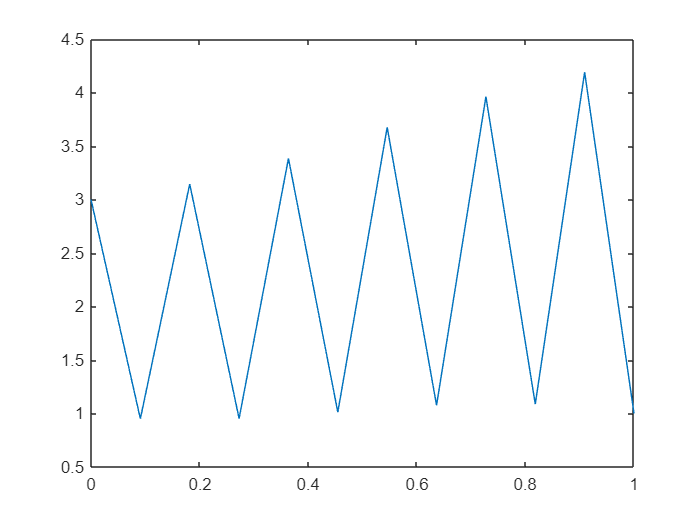

clearvars;
close all;
mu = 1e-3;
alpha = 1;
b = 0;
c =3;
d =1;
L = 1;
%Counts = 2.^(0:13);
Counts = 10^1;
L1 = zeros(length(Counts),1);
L2  = zeros(length(Counts),1);
Linf = zeros(length(Counts),1);
i = 1;
for N = Counts
    
    h = L/(N+1);
    x = (h:h:L-h);
    
    D2 = diag(-2 *ones(N,1)) +diag(ones(N-1,1),1) + diag(ones(N-1,1),-1);
    D2 = 1/h^2 * D2;
    
    D1 = diag(0*ones(N,1)) + diag(ones(N-1,1),1)+diag(-1 * ones(N-1,1),-1);
    D1 = 1/(2*h) * D1;
    
    I = diag(ones(N,1));
    
    A = -mu* D2 + alpha * D1 + b*I;
    
    F = f(x);
    F(1) = F(1) + (alpha/(2*h) + mu/h^2)*c;
    F(end) =  F(end) - (alpha/(2*h) - mu/h^2)*d;
    U = A\F';
    X =[0,x,L];
    


    Y_estim = [c,U',d];
    Y_real = f([0,x,L])/(pi^2 * mu) + (d-c)/L *[0,x,L] + c;
    error =  Y_estim - Y_real;
    L1(i) = 1/(N+2)* sum(abs(error));
    L2(i) = sqrt(1/(N+2)* sum(error .* error));
    Linf(i) = max(error);
    i= i+1
    
    plot(X,Y_estim);
    hold on
    %plot(X,Y_real);
    hold off
    
    %plot(X,abs(Y_real - Y_estim))
end

%loglog(X,abs(Y_real - Y_estim))

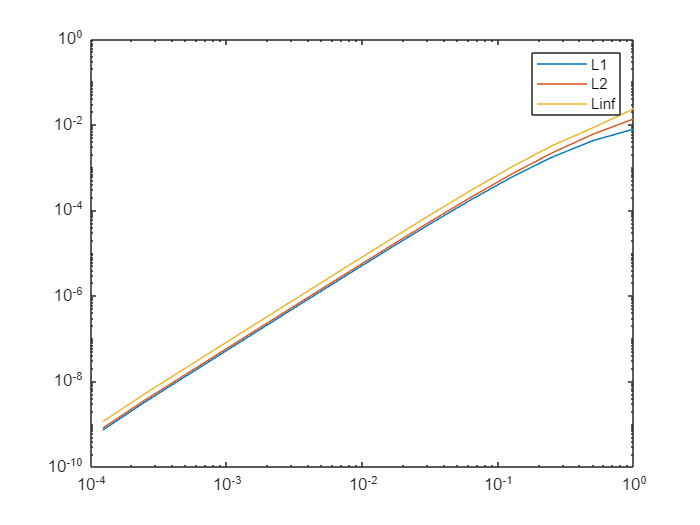

figure(1); clf;

loglog(1./Counts,L1);
hold on

loglog(1./Counts,L2);
loglog(1./Counts,Linf);

legend('L1','L2',"Linf");
hold off

function res = f(x)
    res = sin(pi*x);
end
